%HERE RECONSTRUCTION IS DONE BY LINEAR BIAS PROPOSED METHOD
clear;
close all;
clc;
c1 = 1; % max val of the BL signal
Tmax = 0.45; % Maximum time duration of the signal
dt = 0.000001; % time step for integral as well
Td = 0.000001; % how far I'm placing the sincs
Fm = 50; % Maximum frequency in Hz
BW = 2 * pi * Fm;
integral_value = 0; % integral accumulator
tn = []; % array to store sampling times
current_time = -Tmax; % initialize current time
time_gap = 0;
time_stamps=[];
td = -Tmax:Td:Tmax;
load('god_code.mat', 'fd', 'td'); % Load the existing signal vector and time vector
disp('Loaded existing signal vector from god_code.mat');

Loaded existing signal vector from god_code.mat


fd = c1 * fd / max(abs(fd));
energy = sum(abs(fd).^2) * Td;
tnyq = 1/(2*Fm);
alpha = 0.1;
kappa=1400;
shift=2.2*c1

shift = 2.2000

disp(['Energy of the signal: ', num2str(energy)]);

Energy of the signal: 0.058712



current_index = 1;
f_sampled = [];
% Initialize variables

time_stamps = [time_stamps,-Tmax]; % array to store the difference in times, tk+1 - tk

f_n=[];
f_n=[f_n,shift];
a=1;
b1=0;
at=0;
feed = zeros(size(fd));
loc=[];
td = td(:).';
running_integral=0;
delta_values=[];
delta_values=[delta_values,0];
running_area=0;
sum=0;
signal_running_integral=0;
tn=[];
while current_time <= Tmax

   if current_index > 1
    running_integral = running_integral + (((fd(current_index) - fd(current_index - 1)) / Td)^2) * Td;
    signal_running_integral = signal_running_integral + ((fd(current_index))^2)*Td;
    else
     running_integral = running_integral + ((fd(current_index) / Td)^2) * Td;
     running_integral = 0;
   end
    running_delta =1/sqrt(((1*running_integral)+kappa*signal_running_integral));
    %running_delta =1/sqrt(((running_integral)));
    running_area= (fd(current_index)^2)*dt +running_area;
    running_area1=1/(pi*sqrt(alpha*running_area));
    running_bias= c1+running_area1;
    integral_value = integral_value + fd(current_index) * dt + running_bias * dt;
    sum=sum+running_bias*dt;
    % Check if the integral exceeds the threshold
    if abs(integral_value) >= 1*running_delta
        tn = [tn, current_time];
        f_sampled = [f_sampled, fd(current_index)];
        time_stamps = [time_stamps, time_gap];
        loc=[loc,current_index];
        delta_values = [delta_values, running_delta];
        
        f_n = [f_n,((integral_value - sum)/time_gap)];
        sum=0;
        running_integral = 0;
        signal_running_integral = 0;
        running_area= 0;
        integral_value = 0;
        time_gap = 0;
    end
    % Increment the current time and index
    current_time = current_time + dt;
    current_index = current_index + 1;
    time_gap = time_gap + dt;
end
NoF=length(time_stamps)-1;


iter=5;
F_est = signal_reconstruction(NoF, td, f_n, time_stamps, loc, tn, BW, Fm, iter);
10 * log10( norm(fd(30000:end-30000) - F_est(30000:end-30000,iter))^2 / norm(fd(30000:end-30000)).^2 )

ans = -54.0205

disp(['Length of td: ', num2str(length(td))]);

Length of td: 900001


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 900001


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [900001 5]


disp(['iter: ', num2str(iter)]);

iter: 5


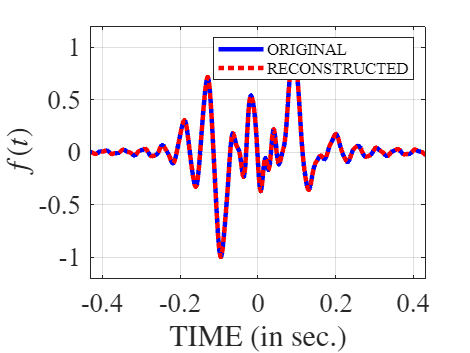






figure;
plot(td, fd/c1, 'b', 'DisplayName', 'ORIGINAL', 'LineWidth', 3); hold on;
plot(td, F_est(:,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED', 'LineWidth', 3); 

xlabel('TIME (in sec.)','FontSize',18,'FontName','Times','Interpreter','Latex');
ylabel('$f(t)$','FontSize',18,'FontName','Times','Interpreter','Latex');
set(gca,'FontSize',18,'FontName','Times');
legend('FontSize', 11);
grid on;
xlim([-0.43, 0.43]);  
ylim([-1.2, 1.2]);  

%exportgraphics(gcf, 'my_figure.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none', 'Resolution', 300);